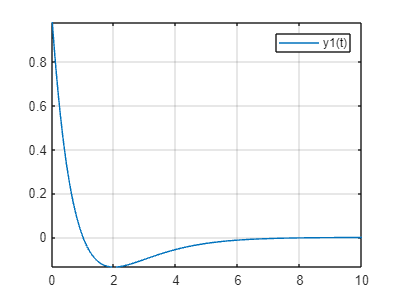

%Ex01
%Sinal 
syms t w tau
y = t*exp(-t)*heaviside(t);
y1 = diff(y, t);
y = subs(y, t, tau);
y2 = int(y, tau, -inf, t);

Y1 = fourier(y1, w);
Y2 = fourier(y2, w);
CONVOL = Y1 * Y2;
convol_y1_y2 = ifourier(CONVOL, t);

figure
fplot(y1, [0 10])
legend('y1(t)')
grid on

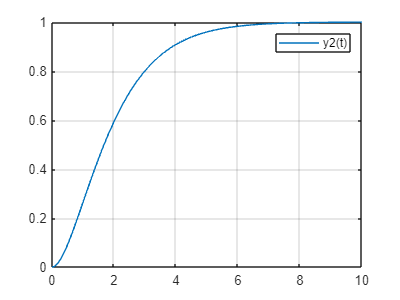

figure
fplot(y2, [0 10])
legend('y2(t)')
grid on

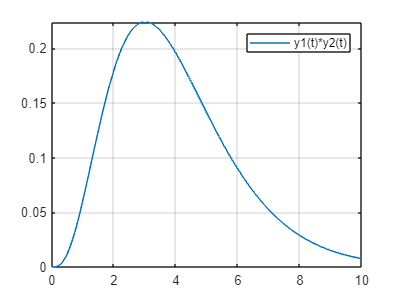

figure
fplot(convol_y1_y2, [0 10])
legend('y1(t)*y2(t)')
grid on

%Ex02
x = exp(-3*t)*heaviside(t);
Rx = int(x*conj(subs(x, t, t-tau)), t, -inf, inf);
Rx = exp(-3*tau);
FAx = fourier(Rx, tau,w)

$$FAx = \mathrm{fourier}\left({\mathrm{e}}^{-3\,\tau },\tau ,w\right)$$